# Testing of TM-CFAR Algorithm against DataSet

clear all;
close all;


## Parameter Selection

PFA = 10^-3 ;
RefWindowSize = 38; %reference window length
GuardCells = 2; % Number of guard cells on each

% trimming variables:
T1 = 4;
T2 = 6;


## TM-CFAR Detection Verification in Time Domain


% Simulated Data
Length = 100000;  %sample length
y_complex = randn(1,Length) + 1i*randn(1,Length); %reference window samples

%TM-CFAR function
%number of cells needed to wrap-around the dataset
wrapFactor = RefWindowSize/2 +GuardCells;

RangeProfiles=  horzcat(y_complex(:, end-wrapFactor+1:end), y_complex(:, 1:end), y_complex(:,1:wrapFactor));%extension of dataset by wrapping around
[detections, false_alarm_count] = TM_CFAR_2D(RangeProfiles, PFA, RefWindowSize, GuardCells, T1, T2);%TM-CFAR algorithm run on dataset
detections = detections(:, wrapFactor+1:end-wrapFactor);%the results of the TM-CFAR algorthm converted back to the original dataset size

%PFA error verification
PFA_expected = PFA*Length;
PFA_simulation = false_alarm_count;
PFA_errorTime = (PFA_expected - PFA_simulation)/PFA_expected*100;
disp("Question 1")

Question 1


disp("PFA expected is " + PFA_expected)

PFA expected is 100


disp("PFA simulation is " + PFA_simulation)

PFA simulation is 93


disp("PFA error is " + PFA_errorTime + "%")

PFA error is 7%


## TM-CFAR Detections in the Time Domain


%% Load Data
[FileName,Path2RadarData,filter_index]=uigetfile('','Select Radar Dataset');
RadarData = load([Path2RadarData filesep FileName]);

%% Extract Range Profiles before, after Equalisation and after Notch filtering

RangeProfiles_BeforeEq = RadarData.RangeLines_BeforeEq;
RangeProfiles_AfterEq = RadarData.RangeLines_AfterEq;
RangeProfiles_AfterEqNotch = RadarData.RangeLines_AfterEQ_Notch;

%% Extract other radar parameters

 PRF_Hz = RadarData.Info.PRF_Hz;
 Bandwidth_Hz = RadarData.Info.Bandwidth_Hz;
 RangeStart_m = RadarData.Info.RangeStart_m;
 BlindRange_m = RadarData.Info.BlindRange_m;
 
[NumOfPulses,NumOfRangeBins]=size(RangeProfiles_AfterEqNotch);

wrapFactor = RefWindowSize/2 +GuardCells;
RangeProfiles_AfterEq=  horzcat(RangeProfiles_AfterEqNotch(:, end-wrapFactor+1:end), RangeProfiles_AfterEqNotch(:, 1:end), RangeProfiles_AfterEqNotch(:,1:wrapFactor)); %extension of dataset by wrapping around
[Detection_matrix1, detection_count_matrix1, Threshold_ave] = TM_CFAR_2D(RangeProfiles_AfterEq, PFA, RefWindowSize, GuardCells, T1, T2);
Detection_matrix1 = Detection_matrix1(:, wrapFactor+1:end-wrapFactor);
Threshold_ave

Threshold_ave = 2.2635e-04

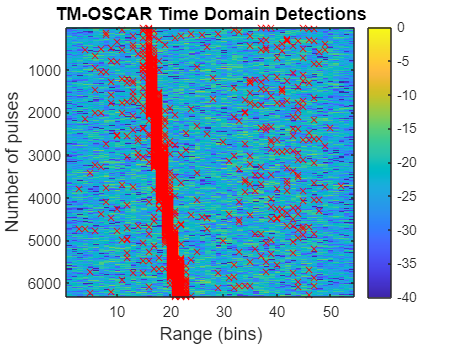


%plotting
fontsize1 = 12;
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('TM-CAR Time Domain Detections','fontsize',fontsize1);
hold on

[pulseCoord, rangeCoord] = find(Detection_matrix1 == 1);

% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'rx');

## TM-CFAR Detection Verification in Frequency Domain


%creation of simulated data
NumberOfPulses = 2000; 
NumberOfRangeBins = 10; 
RangeProfilesSimulated = randn(NumberOfPulses, NumberOfRangeBins) + 1i*randn(NumberOfPulses, NumberOfRangeBins);


%TM-CFAR algorthm along slow time 
detection_matrix = zeros(NumberOfPulses, NumberOfRangeBins);
false_alarm_count_matrix = zeros(1, NumberOfRangeBins);

%Length of CPI
frameLength = 150;
frameNum = round(NumberOfPulses/frameLength); %Number of CPIs

%loop that runs through each CPI and implements the CA-CFAR algorithm along
%the slow-time dimesion
for n = 1:frameNum
    %wrap around required for first CPI
    if n == 1
        StartIdx = 1 + (n-1)*frameLength;
        StopIdx = frameLength + (n-1)*frameLength+ wrapFactor; %wraps around into the next CPI
        frame = RangeProfilesSimulated(StartIdx:StopIdx, :);
        frame = vertcat(RangeProfilesSimulated( end-wrapFactor+1:end, :), frame(1:end, :));%Wraps around into the last CPI
    %wrap-around for standard CPIs     
    elseif n == frameNum
        StartIdx = 1 + (n-1)*frameLength - wrapFactor +1; %wraps around into the previous CPI
        StopIdx = frameLength + (n-1)*frameLength;
        frame = RangeProfilesSimulated(StartIdx:StopIdx, :);
        frame = vertcat(frame(1:end, :), RangeProfilesSimulated(1:wrapFactor,:) ); %wraps around back into the first CPI
   %standard wrap-around for CPIs 
    else
        StartIdx = 1 + (n-1)*frameLength - wrapFactor +1;%wraps around into the previous CPI
        StopIdx = frameLength + (n-1)*frameLength+ wrapFactor;%wraps around into the next CPI
        frame = RangeProfilesSimulated(StartIdx:StopIdx, :);
    end 

    RangeDopplerSimulated = (fft(frame, [ ], 1)); %coversion of CPI to Doppler-range
    temp_detect_matrix_transposed = zeros(NumOfRangeBins, frameLength);
    temp_detect_count_transposed = zeros(NumOfRangeBins, 1);
    [temp_detect_matrix_transposed, temp_detect_count_transposed, Threshold_ave] = TM_CFAR_2D(transpose(RangeDopplerSimulated), PFA, RefWindowSize, GuardCells, T1, T2); %TM-CFAR along the slow dimension
    temp_detect_matrix = transpose(temp_detect_matrix_transposed); %coversion back to correct dimension. Initial transpose was needed so algorithm would run along slow dimension
    temp_detect_count = transpose(temp_detect_count_transposed);

    temp_detect_matrix = temp_detect_matrix(wrapFactor+1:end-wrapFactor, :);
    
    %Single detection in a range bin means entire range bin is designated
    %as target locations:
    columns_with_ones = any(temp_detect_matrix, 1); 
    detection_matrix(StartIdx:StopIdx, columns_with_ones) = 1;

    false_alarm_count_matrix= false_alarm_count_matrix + temp_detect_count;
    
end

%PFA error calculation
PFA_expected = PFA*Length;
PFA_simulation_avg = (sum(false_alarm_count_matrix))/length(false_alarm_count_matrix);
PFA_errorTime = (PFA_expected - PFA_simulation_avg)/PFA_expected*100;
disp("Question 3")

Question 3


disp("PFA expected is " + PFA_expected)

PFA expected is 100


disp("Average PFA simulation is " + PFA_simulation_avg)

Average PFA simulation is 2.5


disp("PFA error is " + PFA_errorTime + "%")

PFA error is 97.5%


## TM-CFAR Detections in the Frquency Domain

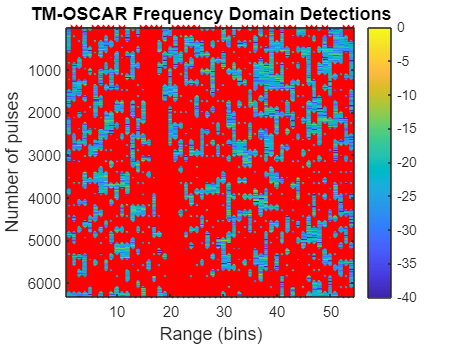


%Conversion to frequency domain
[NumOfPulses,NumOfRangeBins]=size(RangeProfiles_AfterEqNotch);
RangeDoppler = (fft(RangeProfiles_AfterEqNotch, [ ], 1)); 

%TM-CFAR algorthm along slow time 
Length = NumOfPulses;
Detection_matrix2 = zeros(NumOfPulses, NumOfRangeBins);
detection_count_matrix2 = zeros(1, NumOfRangeBins);
Threshold_ave_matrix = [];

%Length of CPI
frameLength = 128;
frameNum = floor(NumOfPulses/frameLength);

%loop that runs through each CPI and implements the TM-CFAR algorithm along
%the slow-time dimesion - SAME LOOP AS SIMULATED DATASET
for n = 1:frameNum
    if n == 1
        StartIdx = 1 + (n-1)*frameLength;
        StopIdx = frameLength + (n-1)*frameLength+ wrapFactor;
        frame = RangeProfiles_AfterEqNotch(StartIdx:StopIdx, :);
        frame = vertcat(RangeProfiles_AfterEqNotch( end-wrapFactor+1:end, :), frame(1:end, :));
    elseif n == frameNum
        StartIdx = 1 + (n-1)*frameLength - wrapFactor +1;
        StopIdx = frameLength + (n-1)*frameLength;
        frame = RangeProfiles_AfterEqNotch(StartIdx:StopIdx, :);
        frame = vertcat(frame(1:end, :), RangeProfiles_AfterEqNotch(1:wrapFactor,:) );
    else
        StartIdx = 1 + (n-1)*frameLength - wrapFactor +1;
        StopIdx = frameLength + (n-1)*frameLength+ wrapFactor;
        frame = RangeProfiles_AfterEqNotch(StartIdx:StopIdx, :);
    end 

    rangeDoppler = (fft(frame, [ ], 1));
    temp_detect_matrix_transposed = zeros(NumOfRangeBins, frameLength);
    temp_detect_count_transposed = zeros(NumOfRangeBins, 1);
    [temp_detect_matrix_transposed, temp_detect_count_transposed, Threshold_ave] = TM_CFAR_2D(transpose(rangeDoppler), PFA, RefWindowSize, GuardCells, T1, T2);
    temp_detect_matrix = transpose(temp_detect_matrix_transposed);
    temp_detect_count = transpose(temp_detect_count_transposed);
    Threshold_ave_matrix(end+1) = Threshold_ave;

    temp_detect_matrix = temp_detect_matrix(wrapFactor+1:end-wrapFactor, :);

    columns_with_ones = any(temp_detect_matrix, 1);
    Detection_matrix2(StartIdx:StopIdx, columns_with_ones) = 1;

    detection_count_matrix2 = detection_count_matrix2 + temp_detect_count;
    
end

%plottinn
fontsize1 = 12;
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('TM-CAR Frequency Domain Detections','fontsize',fontsize1);
hold on

[pulseCoord, rangeCoord] = find(Detection_matrix2 == 1);

% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'rx');

## AND gate combination

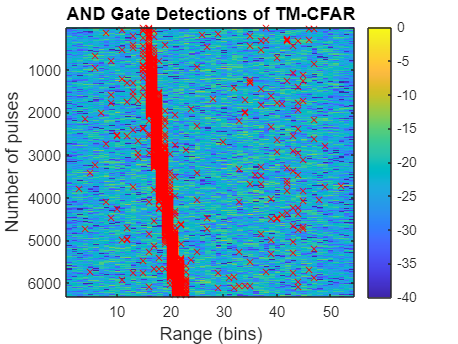


%The combination of the detection algotthms to reduce false alarmsa:
% AND gate attempt
Detections = zeros(NumOfPulses, NumOfRangeBins);
for j = 1:NumOfRangeBins
    for i = 1: NumOfPulses
        if (Detection_matrix1(i,j) == Detection_matrix2(i,j)) && (Detection_matrix1(i,j) == 1) 
            Detections(i,j) = 1;
        else
            Detections(i,j) = 0;
        end
    end
end

%plotting
fontsize1 = 12;
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('AND Gate Detections of TM-CFAR','fontsize',fontsize1);
hold on

[pulseCoord, rangeCoord] = find(Detections == 1);
% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'rx');

## Detection Performance Test

dataset = FileName(1:2)

dataset = '01'

dataset = str2num(dataset)

dataset = 1


[numRows,numCols] = size(Detections);
Target_locations = zeros(numRows, numCols);

%loading of required dataset
if dataset == 1
    load("Target_locations_DS1.mat");
    Target_locations = Target_locations_DS1;
elseif dataset == 2
    load("Target_locations_DS2.mat");
    Target_locations = Target_locations_DS2;
elseif dataset == 3
    load("Target_locations_DS3.mat");
    Target_locations = Target_locations_DS3;
elseif dataset == 4
    load("Target_locations_DS4.mat");
    Target_locations = Target_locations_DS4;
elseif dataset == 5
    load("Target_locations_DS5.mat");
    Target_locations = Target_locations_DS5;
else 
    load("Target_locations_DS6.mat");
    Target_locations = Target_locations_DS6;
end

%detection performance test run on AND gate processing
[DetectionAccPerCellAND, DetectionAccPerTargetAND, false_alarms_perCellAND, missed_detections_perCellAND, detections_perTargetAND, missed_detections_perTargetAND, false_alarms_perTargetAND] = DetectionAccTest(Target_locations, Detections );
display("Detection accuracy per cell (AND): "+DetectionAccPerCellAND )

    "Detection accuracy per cell (AND): 84.4365"



display("Detection accuracy per target (AND): "+DetectionAccPerTargetAND)

    "Detection accuracy per target (AND): 92.154"




%detection performance test run on time domain
[DetectionAccPerCellTime, DetectionAccPerTargetTime, false_alarms_perCellTime, missed_detections_perCellTime, detections_perTargetTime, missed_detections_perTargetTime, false_alarms_perTargetTime] = DetectionAccTest(Target_locations, Detection_matrix1 );
display("Detection accuracy per cell (time domain): "+DetectionAccPerCellTime )

    "Detection accuracy per cell (time domain): 85.4721"



display("Detection accuracy per target (time domain): "+DetectionAccPerTargetTime )

    "Detection accuracy per target (time domain): 92.9682"




%detection performance test run on freq domain
[DetectionAccPerCellFreq, DetectionAccPerTargetFreq, false_alarms_perCellFreq, missed_detections_perCellFreq, detections_perTargetFreq, missed_detections_perTargetFreq, false_alarms_perTargetFreq] = DetectionAccTest(Target_locations, Detection_matrix2);
display("Detection accuracy per cell(freq domain): "+DetectionAccPerCellFreq)

    "Detection accuracy per cell(freq domain): 98.7919"



display("Detection accuracy per target (freq domain): "+DetectionAccPerTargetFreq)

    "Detection accuracy per target (freq domain): 99.1858"



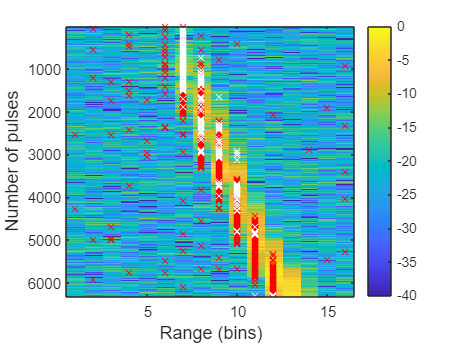




%trimming datasets to focus on target locations
if dataset == 1
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,10:25);
    detections_perTargetAND = detections_perTargetAND(:,10:25);
    missed_detections_perTargetAND = missed_detections_perTargetAND(:,10:25);

end

if dataset == 2
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,11:22);
    detections_perTargetAND = detections_perTargetAND(:,11:22);
    missed_detections_perTargetAND = missed_detections_perTargetAND(:,11:22);

end


if dataset == 3
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,680:730);
    detections_perTargetAND = detections_perTargetAND(:,680:730);
    missed_detections_perTargetAND = missed_detections_perTargetAND(:,680:730);

end
if dataset == 4
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,131:226);
    detections_perTargetAND = detections_perTargetAND(:,131:226);
    missed_detections_perTargetAND = missed_detections_perTargetAND(:,131:226);

end
if dataset == 5
    RangeProfiles_AfterEqNotch = horzcat(RangeProfiles_AfterEqNotch(:,415:476), RangeProfiles_AfterEqNotch(:,790:810));
    detections_perTargetAND = horzcat(detections_perTargetAND(:,415:476), detections_perTargetAND(:,790:810));
    missed_detections_perTargetAND = horzcat(missed_detections_perTargetAND(:,415:476), missed_detections_perTargetAND(:,790:810));

end

if dataset == 6
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,1:280);
    detections_perTargetAND = detections_perTargetAND(:,1:280);
    missed_detections_perTargetAND = missed_detections_perTargetAND(:,1:280);

end

%plotting
fontsize1 = 12;
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Detections and Missed Detections (AND Processing)','fontsize',fontsize1);
hold on

%detected locations are red
[pulseCoord, rangeCoord] = find(detections_perTargetAND == 1);
% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'rx');

%detected locations are white
[pulseCoord, rangeCoord] = find(missed_detections_perTargetAND == 1);
% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'wx');

## False Alarm Check

PFA_expected = PFA*NumOfPulses*NumOfRangeBins;
PFA_datasetTime = sum(false_alarms_perTargetTime(:));
PFA_errorTime = (PFA_expected - PFA_datasetTime)/PFA_expected*100;
PFA_datasetFreq = sum(false_alarms_perTargetFreq(:));
PFA_errorFreq = (PFA_expected - PFA_datasetFreq)/PFA_expected*100;
PFA_datasetAND = sum(false_alarms_perTargetAND(:));
PFA_errorAND = (PFA_expected - PFA_datasetAND)/PFA_expected*100;

disp("PFA Estimates")

PFA Estimates


disp("PFA expected is " + PFA_expected)

PFA expected is 341.064


disp("*****************************************************")

*****************************************************


disp("PFA of Dataset from time domain processing is " + PFA_datasetTime)

PFA of Dataset from time domain processing is 284


disp("PFA error from time domain processing is is " + PFA_errorTime + "%")

PFA error from time domain processing is is 16.7312%


disp("*****************************************************")

*****************************************************


disp("PFA of Dataset from frequency domain processing is " + PFA_datasetFreq)

PFA of Dataset from frequency domain processing is 112713


disp("PFA error from frequency domain processing is is " + PFA_errorFreq + "%")

PFA error from frequency domain processing is is -32947.4632%


disp("*****************************************************")

*****************************************************


disp("PFA of Dataset from AND gate processing is " + PFA_datasetAND)

PFA of Dataset from AND gate processing is 159


disp("PFA error from AND processing is is " + PFA_errorAND + "%")

PFA error from AND processing is is 53.3812%


function [Detections, detection_count, Threshold_ave] = TM_CFAR_2D(input, PFA, RefWindowSize, GuardCells, T1, T2)%optimised TM-CFAR algorithm - all range lines at a time
[numRows,numCols] = size(input);
Threshold = zeros(numRows, numCols);
Detections = zeros(numRows, numCols);
detection_count = zeros(numRows, 1);

%Square Law detector:
DataAfterPowerLawDetector = abs(input).^2 ;


% Threshold factor:
syms T p;
M1 = symprod((RefWindowSize-p)/(RefWindowSize+T*(RefWindowSize -T1 -T2) - p), p, 0, T1);
Mi = symprod(((RefWindowSize - T1 - p +1)/(RefWindowSize - T1 - T2 - p +1))/(((RefWindowSize - T1 - p +1)/(RefWindowSize - T1 - T2 - p +1))+T), p, 2, RefWindowSize - T1 - T2);
f = M1*Mi - PFA;
fh = matlabFunction(f);
root = fzero(fh, 5);
alpha = root;

%Start and Stop Indices for algorthm:
startIndx = RefWindowSize/2 + GuardCells+ 1;
stopIndx = numCols - RefWindowSize/2 - GuardCells;

% Threshold calculation:
for p = (startIndx):(stopIndx)
    % Calculate the reference cells in the leading and lagging windows
    reference_leading = (DataAfterPowerLawDetector(:, p + GuardCells + 1 : p + GuardCells + RefWindowSize/2));
    reference_lagging = (DataAfterPowerLawDetector(:, p - RefWindowSize/2 - GuardCells: p - GuardCells - 1));

    %Trimming of reference window
    reference_window = horzcat(reference_lagging, reference_leading);
    reference_window = sort(reference_window, 2);
    reference_window_trimmed = reference_window(:, 1+T1:end - T2);
    reference_window_sum = sum(reference_window_trimmed, 2);


    % Calculate threshold using scaling factor
    Threshold(:, p) = alpha.*reference_window_sum;

    %Detection calculated
    Detections(:,p) = DataAfterPowerLawDetector(:, p) > Threshold(:, p);
    detection_count = detection_count + Detections(:,p);
end
Threshold_ave = (sum(Threshold(:)))/(numCols*numRows);
end

%detection performance test
function [DetectionAccPerCell, DetectionAccPerTarget, false_alarms_perCell, missed_detections_perCell, detections_perTarget, missed_detections_perTarget, false_alarms_perTarget] = DetectionAccTest(Target_locations, Detections )

%variable creation
[numRows,numCols] = size(Target_locations);
num_detections_perCell = 0;
detections_perCell = Detections;
Target_locations_perCell = Target_locations;
missed_detections_perCell = zeros(numRows,numCols);
false_alarms_perCell = Detections;


num_detections_perTarget = 0;
detections_perTarget = Detections;
target_locations_perTarget = Target_locations;
missed_detections_perTarget = zeros(numRows,numCols);
false_alarms_perTarget = Detections;

%variable used to acount for target sidelobes so they are not assumed as
%missed detections
targetSize = 10;
% DS1 = 3
% DS2 = 3
% DS3 =10
% DS4 = 10
% DS5 = 10
% DS6 = 10

%this method does not account for target sidelobes
for i = 1:numRows
    for j = 1:numCols
        if (detections_perCell(i,j) == Target_locations_perCell(i,j))  && (detections_perCell(i,j) == 1)
            num_detections_perCell = num_detections_perCell +1;
            false_alarms_perCell(i,j) = 0;
            
        elseif Target_locations_perCell(i,j) == 1 && (detections_perCell(i,j) == 0)
            missed_detections_perCell(i,j) = 1;
        end
        
    end
   
end

%this method accounts for target sidelobes 
for i = 1:numRows
    for j = 1:numCols
        if (detections_perTarget(i,j) == target_locations_perTarget(i,j))  && (detections_perTarget(i,j) == 1)
            num_detections_perTarget = num_detections_perTarget +1;
            detections_perTarget(i, j+1:j+3) = 0; %removes target points in vicinity if the target as already been detected so it is not measured more than once
            target_locations_perTarget(i, j+1:j+targetSize) = 0; %removes ground truths in vicinity as this target has already been detected
            target_locations_perTarget(i, j-targetSize:j-1) = 0;
            false_alarms_perTarget(i, j-targetSize:j+targetSize) = 0; %removes false alarms as this target has been detected
        end
        
    end
end
for i = 1:numRows
 for j = 1:numCols
        if target_locations_perTarget(i,j) ==1 && (detections_perTarget(i,j) == 0)
            missed_detections_perTarget(i,j) = 1;
            target_locations_perTarget(i, j+1:j+targetSize) = 0;
            target_locations_perTarget(i, j-targetSize:j-1) = 0;
        end
 end
end



total_detections_perCell = sum(Target_locations(:) == 1);
total_detections_perTarget = sum(target_locations_perTarget(:) == 1);


DetectionAccPerCell = num_detections_perCell/total_detections_perCell*100;
DetectionAccPerTarget = num_detections_perTarget/total_detections_perTarget*100;

end